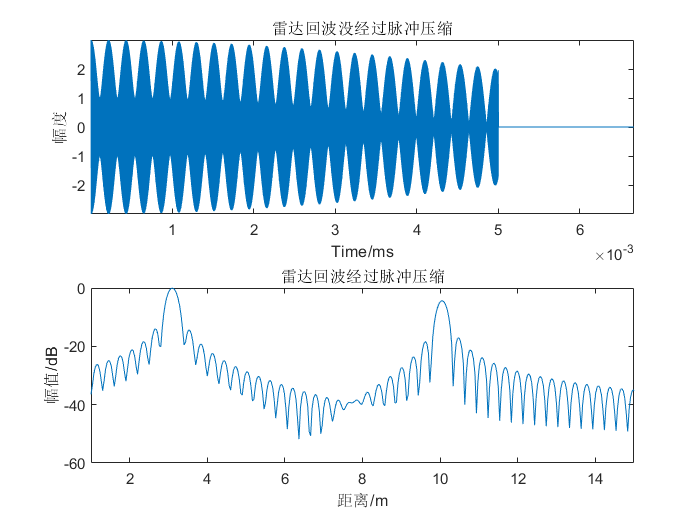

%% LFM 脉冲压缩雷达
%-----------------------------------------
T = 10e-3;                  %未压缩脉冲时宽
Tr = 100e-3;                %脉冲重复周期
B = 1e9;                  %信号带宽
Rmin = 1;                 %最小测距
Rmax = 10e5;                %最大测距
RCS = [1 1 1];              %散射系数矩阵
%  R = [2 5 10];          %目标点位置
 R = [3 3.1 10];

%------------------------------------------
c = 3e8;                %光速
K = B/T;                %线性调频斜率
Rwid = Rmax - Rmin;     %最大测量距离
Twid = 2*Rwid/c;        %回波窗长度
Fs = 4*B;               %采样率
Ts = 1/Fs;              %采样时间
Nwid = ceil(Twid/Ts);   %采样窗内采样点数

%-------------------------------------------
%%产生反射回波
t = linspace(2*Rmin/c,2*Rmax/c,Nwid);

M = length(R);
td = ones(M,1)*t-2*R'/c*ones(1,Nwid);
Srt = RCS*(exp(1j*pi*K*td.^2).*(abs(td)<T/2));

%---------------------------------------------
%%数字信号处理 脉冲压缩
Nchirp = ceil(T/Ts);                               %脉冲宽度离散化
Nfft = 2^nextpow2(Nwid+Nwid-1);                    %方便使用FFT算法，满足2的次方形式 
                                                          
Srw = fft(Srt,Nfft);                               %回波做FFT
t0 = linspace(-T/2,T/2,Nchirp); 
St = exp(1j*pi*K*t0.^2);                           %线性调频信号原始信号作为参考信号  
% % 加窗处理
% win=blackman(Nwid)';
% St_w=St.*win';

Sw = fft(St,Nfft);                                   %参考信号做FFT
Sot = fftshift(ifft(Srw.*conj(Sw)));                 %脉冲压缩后的信号

N0=Nfft/2-Nchirp/2;
Z=abs(Sot(N0:N0+Nwid-1));
Z=Z/max(Z);
Z=20*log10(Z+1e-6);
%figure
subplot(211)
plot(t,real(Srt));
axis tight;
xlabel('Time/ms');ylabel('幅度')
title('雷达回波没经过脉冲压缩');
subplot(212)
plot(t*c/2,Z)
axis([1,15,-60,0]);
xlabel('距离/m');ylabel('幅值/dB')
title('雷达回波经过脉冲压缩');